for k =1:1:length(ID)
    copy{k,1} = ID(k);
    copy{k,2} = activity{k};    
end


## Histograma de cantidad de datos por ID

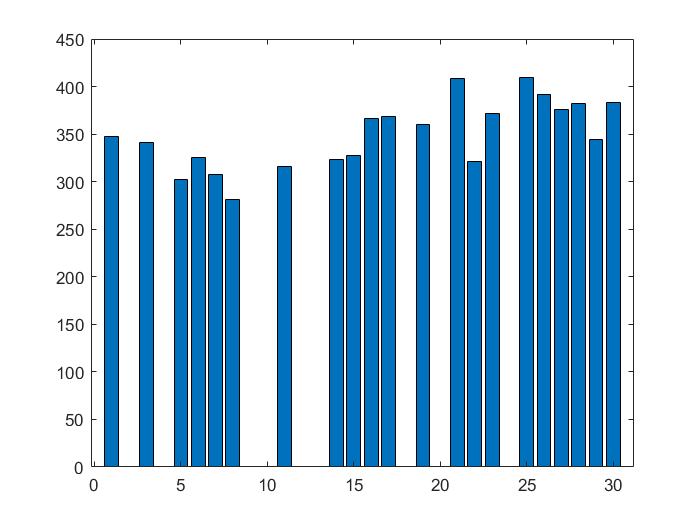

num_data = zeros(1,30); 
val = 0;

while(val < 30)
    val = val + 1;
    
    for k =1:1:length(ID)
        if ID(k) == val
            num_data(val) = num_data(val) + 1;
        end       
    end
end
x = [1:30];
bar(x,num_data)

## Histrograma ID con pruebas

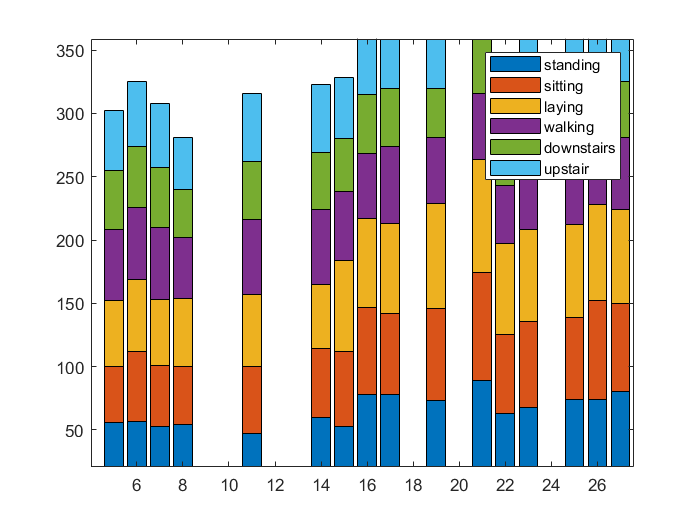

%1 standing, 2 sitting, 3 laying, 4 walking 5 downstiar 6upstair
activities = zeros(6,30);

for k =1:1:30 %varia el ID
    
    for j = 1:1:7352 % Barre todas las muestras
        temp_id = copy{j,1}; %temporal para el ID
        
        if  temp_id == k % si temp_ID es igual al ID busque atividad es
            temp = copy{j,2}; %almacena la actividad
            if  strcmp(temp, 'standing') == 1
                activities(1,k) = activities(1,k) + 1;
            elseif strcmp(temp,'sitting') == 1
                activities(2,k) = activities(2,k) + 1;
            elseif strcmp(temp,'laying') == 1
                activities(3,k) = activities(3,k) + 1;
            elseif strcmp(temp,'walking') == 1
                activities(4,k) = activities(4,k) + 1;
            elseif strcmp(temp,'downstairs') == 1
                activities(5,k) = activities(5,k) + 1;
            elseif strcmp(temp,'upstairs') == 1
                activities(6,k) = activities(6,k) + 1;
            end
        end        
    end
    
end

bar(x,activities,'stacked'),legend('standing','sitting','laying','walking','downstairs','upstair')

## Numero total de muestras por actividad

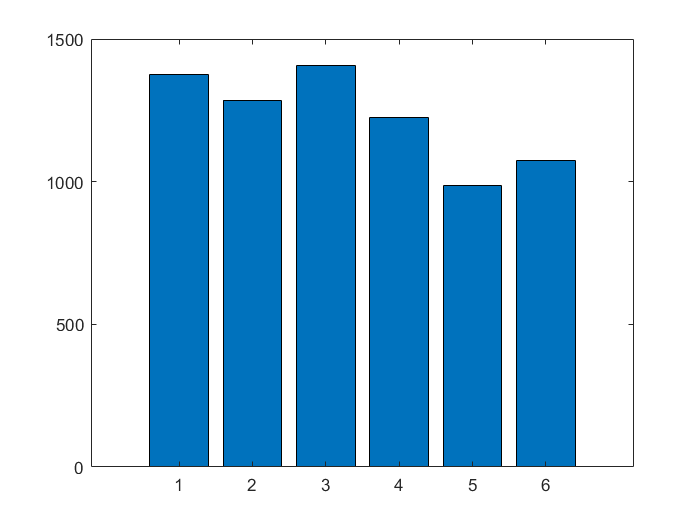

num_act = zeros(1,6);
for k =1:1:6
    temp = sum(activities(k,:));
    num_act(k) = temp;
end
 
bar(num_act)